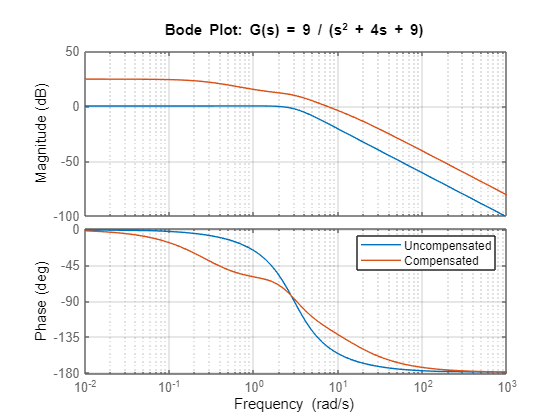

% ============================================================
% Case 1: G(s) = 9/(s^2 + 4s + 9)
% Author: Joshua Muthenya Wambua
% Reg. No: EG209/109705/22
% ============================================================

clc; clear; close all;
s = tf('s');

G = 9/(s^2 + 4*s + 9);
C_lead = 10*(s+2)/(s+12);
C_lag  = (s+3)/(s+0.3);
C_total = C_lead * C_lag;

T_uncomp = feedback(G,1);
T_comp   = feedback(C_total*G,1);

figure;
bode(G, C_total*G); legend('Uncompensated','Compensated');
title('Bode Plot: G(s) = 9 / (s^2 + 4s + 9)'); grid on;

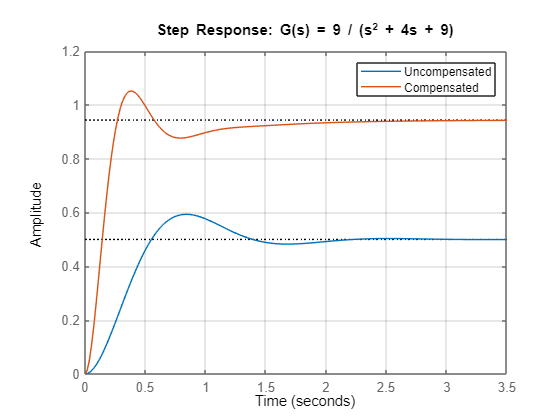


figure;
step(T_uncomp, T_comp);
legend('Uncompensated','Compensated');
title('Step Response: G(s) = 9 / (s^2 + 4s + 9)'); grid on;